# Offline RL for GBWM — Week 6.0: Plan C reward + Stress-Day Oversampling

Diagnosis from Week 5: Plan C drawdown-penalty reward delivered the first across-the-board tail-risk improvement (MaxDD P90 12.87% -> 11.79%, worst Sharpe -5.78 -> -5.38). But residual tail loss remains because TRAIN and TEST are drawn from very different macro regimes: - Train (2010-Q1 -> 2019-Q4): mostly bull market, low VIX, normal curve -> stress days (VIX_z>1.5 OR T10Y2Y_z<-1.5) account for only ~17% - Test (2022-Q1 -> 2024-Q3): hiking cycle + stock-bond co-crash + AI rally -> stress days account for ~40% The agent simply has not seen enough stress regime to learn how to act in it.

Week 6.0 keeps Plan C reward UNCHANGED and only modifies episode-start sampling: instead of uniform sliding step, draw start indices with weight proportional to the stress intensity of the resulting horizon window. This rebalances the offline dataset so train stress occupation approaches test.

Stress intensity per day: stressScore(t) = max(0, VIX_z(t)) + max(0, -T10Y2Y_z(t)) Window weight (continuous, NOT a hard threshold): weight(s) = sum(stressScore(s : s+H-1)) + epsilon Episode starts drawn via randsample(starts, N, true, weight).

NO leakage: - stressScore uses train-only z-scores (macroMean/macroStd fit on train). - Candidate starts are clamped to [1, trainingRange - horizonPeriods + 1]. - Test data is never touched by the weighting machinery.

Everything else (reward, network, agent, seeds, eval protocol) IDENTICAL to week5_drawdown_penalty.m, so any delta is attributable to oversampling.

clear; clc;

## Fixed Parameters (inherited from Plan C)

initialWealth   = 100000;
goalWealth      = 102000;
contribution    = 0;
rebalanceStep   = calmonths(1);

trainingRange   = 2515;
horizonPeriods  = 30;
numEpisodes     = 165;
numActions      = 15;

logsRoot        = fullfile("experiments", "logs", "week6_0_oversample");

hiddenUnits     = 32;
maxEpochs       = 100;
stepsPerEpoch   = 400;
miniBatchSize   = 256;
discountFactor  = 0.995;

seeds           = [1000 2000 3000 4000 5000];
nSeeds          = numel(seeds);

numEvalEpisodes = 30;
evalStepSize    = 30;

% Plan C reward (UNCHANGED)
BETA   = 5.0;
DD_THR = 0.03;

% NEW — oversampling sharpness. epsilon large -> closer to uniform,
% epsilon small -> more biased toward stress windows. Start at 0.5 (mild);
% if train stress occupation still well below test, drop to 0.1.
EPSILON_WEIGHT = 0.5;

% Macro column indices in z-scored matrix [DGS10_z, T10Y2Y_z, VIXCLS_z, DFF_z]
COL_T10Y2Y = 2;
COL_VIX    = 3;

## Load price data

pricesTT   = readtable("data/prices_train.csv");
assetNames = pricesTT.Properties.VariableNames(2:end);
P_train    = pricesTT{:, 2:end};
R_train    = diff(log(P_train));

R_sub = R_train(1:trainingRange, :);
mu    = mean(R_sub, 1)';
Sigma = cov(R_sub);

p = Portfolio("AssetList", assetNames);
p = setDefaultConstraints(p);
p = setAssetMoments(p, mu, Sigma);
W_frontier = estimateFrontier(p, numActions);

## Load macro data, z-score on train

macroTT   = readtable("data/macro_train.csv");
M_train   = macroTT{:, 2:end};
macroMean = mean(M_train, 1);
macroStd  = std(M_train, 0, 1);
macroStd(macroStd == 0) = 1;
M_train_z = (M_train - macroMean) ./ macroStd;

## Load + z-score test data

[R_full, M_test_z] = inputTestData('data/prices_test.csv', 'data/macro_test.csv', ...
                                    macroMean, macroStd);

## --- Build stress-weighted start distribution (train-only, computed once) ---

Per-day stress intensity (continuous, train z-scores).

stressScoreDay = max(0, M_train_z(:, COL_VIX)) + max(0, -M_train_z(:, COL_T10Y2Y));

% Reference stress-flag rates (for diagnostic readouts)
isStressDay_train = (M_train_z(:, COL_VIX) > 1.5) | (M_train_z(:, COL_T10Y2Y) < -1.5);
trainStressRateBaseline = mean(isStressDay_train(1:trainingRange));
isStressDay_test  = (M_test_z(:, COL_VIX) > 1.5) | (M_test_z(:, COL_T10Y2Y) < -1.5);
testStressRate    = mean(isStressDay_test);

% Candidate episode starts and window-sum weights
candStarts = (1 : (trainingRange - horizonPeriods + 1))';
assert(max(candStarts) + horizonPeriods - 1 <= trainingRange, ...
    "candidate start range overflows train segment");

windowWeights = zeros(numel(candStarts), 1);
for k = 1:numel(candStarts)
    s = candStarts(k);
    windowWeights(k) = sum(stressScoreDay(s : s + horizonPeriods - 1));
end
windowWeights = windowWeights + EPSILON_WEIGHT;   % avoid zero-weight starts

fprintf("=== Stress-day diagnostics ===\n");

=== Stress-day diagnostics ===


fprintf("  Baseline train stress rate (uniform sampling proxy) : %.1f%%\n", ...
    100 * trainStressRateBaseline);

  Baseline train stress rate (uniform sampling proxy) : 17.4%


fprintf("  Test  stress rate (target)                          : %.1f%%\n", ...
    100 * testStressRate);

  Test  stress rate (target)                          : 73.8%


fprintf("  Oversampling epsilon                                : %.2f\n", ...
    EPSILON_WEIGHT);

  Oversampling epsilon                                : 0.50


## Cross-seed result storage

results = struct();
results.successRate     = nan(nSeeds, 1);
results.meanSharpe      = nan(nSeeds, 1);
results.stdSharpe       = nan(nSeeds, 1);
results.meanMaxDD       = nan(nSeeds, 1);
results.stdMaxDD        = nan(nSeeds, 1);
results.meanTermWealth  = nan(nSeeds, 1);
results.p10TermWealth   = nan(nSeeds, 1);
results.p90TermWealth   = nan(nSeeds, 1);
results.minSharpe       = nan(nSeeds, 1);
results.p90MaxDD        = nan(nSeeds, 1);
results.actionHist      = zeros(nSeeds, numActions);
results.penaltyShare    = nan(nSeeds, 1);
results.meanPenalty     = nan(nSeeds, 1);
results.trainStressRate = nan(nSeeds, 1);   % NEW: actual stress rate in sampled episodes

allWealthPathsBySeed = cell(nSeeds, 1);

normalizeWealth = @(w) min(w/goalWealth, 5);
timeFrac        = @(t) t / horizonPeriods;

obsDim = 2 + size(M_train_z, 2);

## Loop over seeds

for sIdx = 1:nSeeds
    seed = seeds(sIdx);
    rng(seed, "twister");

    fprintf("\n========== Seed %d (%d/%d) ==========\n", seed, sIdx, nSeeds);

    seedLogsFolder = fullfile(logsRoot, sprintf("seed_%d", seed));
    if isfolder(seedLogsFolder)
        delete(fullfile(seedLogsFolder, "*.mat"));
    else
        mkdir(seedLogsFolder);
    end

    % --- Draw stress-weighted episode starts (with replacement) ---
    sampledStarts = randsample(candStarts, numEpisodes, true, windowWeights);

    % --- Build offline episodes with Plan C reward ---
    nPenaltySteps     = 0;
    penaltySum        = 0;
    nStressStepsSeen  = 0;
    nTotalStepsSeen   = 0;

    for episodeCount = 1:numEpisodes
        startIdx  = sampledStarts(episodeCount);
        expStruct = repmat(struct("Observation",[],"Action",[],"Reward",[], ...
            "NextObservation",[],"IsDone",[]), horizonPeriods, 1);

        wealth = initialWealth;
        peakW  = initialWealth;

        for t = 1:horizonPeriods
            dayIdx   = startIdx + t - 1;
            macroVec = M_train_z(dayIdx, :)';
            obs      = [normalizeWealth(wealth); timeFrac(t); macroVec];

            aIdx = randi(numActions);
            w    = W_frontier(:, aIdx);

            r_tp1      = R_sub(dayIdx, :) * w;
            wealthNext = (wealth + contribution) * (1 + r_tp1);

            % Plan C reward (unchanged)
            peakW   = max(peakW, wealthNext);
            DD_t    = (peakW - wealthNext) / peakW;
            penalty = BETA * max(0, DD_t - DD_THR);
            reward  = log(wealthNext / wealth) - penalty;

            if penalty > 0
                nPenaltySteps = nPenaltySteps + 1;
                penaltySum    = penaltySum + penalty;
            end

            nStressStepsSeen = nStressStepsSeen + double(isStressDay_train(dayIdx));
            nTotalStepsSeen  = nTotalStepsSeen + 1;

            if t == horizonPeriods && wealthNext >= goalWealth
                reward = reward + 1.0;
            end

            nextDayIdx   = min(dayIdx + 1, size(M_train_z, 1));
            nextMacroVec = M_train_z(nextDayIdx, :)';
            nextObs      = [normalizeWealth(wealthNext); ...
                            timeFrac(min(t+1, horizonPeriods)); ...
                            nextMacroVec];
            isDone       = (t == horizonPeriods);

            expStruct(t).Observation     = {obs};
            expStruct(t).Action          = {aIdx};
            expStruct(t).Reward          = reward;
            expStruct(t).NextObservation = {nextObs};
            expStruct(t).IsDone          = isDone;

            wealth = wealthNext;
        end

        epFile = fullfile(seedLogsFolder, sprintf("loggedData%03d.mat", episodeCount));
        exp = expStruct;
        save(epFile, "exp");
    end

    totalSteps = numEpisodes * horizonPeriods;
    results.penaltyShare(sIdx)    = nPenaltySteps / totalSteps;
    results.trainStressRate(sIdx) = nStressStepsSeen / nTotalStepsSeen;
    if nPenaltySteps > 0
        results.meanPenalty(sIdx) = penaltySum / nPenaltySteps;
    else
        results.meanPenalty(sIdx) = 0;
    end
    fprintf("  Saved %d episodes (%d steps). Stress-day share in sampled episodes: %.1f%% (baseline %.1f%%, test %.1f%%)\n", ...
        numEpisodes, totalSteps, 100*results.trainStressRate(sIdx), ...
        100*trainStressRateBaseline, 100*testStressRate);
    fprintf("  Penalty-active steps: %d (%.1f%%), avg magnitude %.4f\n", ...
        nPenaltySteps, 100*results.penaltyShare(sIdx), results.meanPenalty(sIdx));

    % --- File datastore ---
    myReadFcn = @(fname) load(fname, "exp").exp;
    fds = fileDatastore(fullfile(seedLogsFolder, "loggedData*.mat"), ...
                        "ReadFcn", myReadFcn);

    % --- Build fresh agent ---
    obsInfo = rlNumericSpec([obsDim 1], Name="GBWMObservation");
    actInfo = rlFiniteSetSpec(1:numActions, Name="AllocationIndex");

    criticLG = layerGraph([
        featureInputLayer(obsInfo.Dimension(1), Name="state")
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(numActions, Name="Qout")
        ]);

    criticNet = dlnetwork(criticLG);
    critic    = rlVectorQValueFunction(criticNet, obsInfo, actInfo);

    agentOpts = rlDQNAgentOptions( ...
        DiscountFactor=discountFactor, ...
        ExperienceBufferLength=1e6, ...
        MiniBatchSize=miniBatchSize, ...
        TargetUpdateMethod="periodic", ...
        TargetUpdateFrequency=4, ...
        UseDoubleDQN=true);
    agentOpts.CriticOptimizerOptions.LearnRate         = 5e-4;
    agentOpts.CriticOptimizerOptions.GradientThreshold = 1;
    agent = rlDQNAgent(critic, agentOpts);

    % --- Train ---
    tfdOpts = rlTrainingFromDataOptions( ...
        MaxEpochs        = maxEpochs, ...
        NumStepsPerEpoch = stepsPerEpoch, ...
        Plots            = "none", ...
        Verbose          = false);
    trainFromData(agent, fds, tfdOpts);
    save(fullfile(seedLogsFolder, "TrainedAgent.mat"), "agent");

    % --- Hold-out evaluation (raw wealth, no reward shaping) ---
    successCount   = 0;
    allSharpes     = nan(numEvalEpisodes, 1);
    allMaxDD       = nan(numEvalEpisodes, 1);
    allTermWealth  = nan(numEvalEpisodes, 1);
    allWealthPaths = cell(numEvalEpisodes, 1);
    allActions     = zeros(numEvalEpisodes, horizonPeriods);

    for ep = 1:numEvalEpisodes
        startEval = (ep-1)*evalStepSize + 1;
        if startEval + horizonPeriods - 1 > size(R_full, 1)
            break;
        end

        wealth = zeros(horizonPeriods+1, 1);
        wealth(1) = initialWealth;
        chosenActions = zeros(1, horizonPeriods);
        for t = 1:horizonPeriods
            dayIdx   = startEval + t - 1;
            macroVec = M_test_z(dayIdx, :)';
            obs      = { [normalizeWealth(wealth(t)); timeFrac(t); macroVec] };
            aGreedy  = agent.getAction(obs);
            chosenActions(t) = aGreedy{1};
            w        = W_frontier(:, aGreedy{1});
            r_tp1    = R_full(dayIdx, :) * w;
            wealth(t+1) = (wealth(t) + contribution) * (1 + r_tp1);
        end

        rets    = diff(log(wealth));
        sharpe  = mean(rets) / std(rets) * sqrt(252);
        maxDD   = max(cummax(wealth) - wealth) / max(wealth);

        allSharpes(ep)     = sharpe;
        allMaxDD(ep)       = maxDD;
        allTermWealth(ep)  = wealth(end);
        allWealthPaths{ep} = wealth;
        allActions(ep, :)  = chosenActions;
        successCount       = successCount + double(wealth(end) >= goalWealth);
    end

    results.successRate(sIdx)    = successCount;
    results.meanSharpe(sIdx)     = mean(allSharpes,'omitnan');
    results.stdSharpe(sIdx)      = std(allSharpes,'omitnan');
    results.meanMaxDD(sIdx)      = mean(allMaxDD,'omitnan');
    results.stdMaxDD(sIdx)       = std(allMaxDD,'omitnan');
    results.meanTermWealth(sIdx) = mean(allTermWealth,'omitnan');
    results.p10TermWealth(sIdx)  = prctile(allTermWealth, 10);
    results.p90TermWealth(sIdx)  = prctile(allTermWealth, 90);
    results.minSharpe(sIdx)      = min(allSharpes);
    results.p90MaxDD(sIdx)       = prctile(allMaxDD, 90);
    for a = 1:numActions
        results.actionHist(sIdx, a) = sum(allActions(:) == a);
    end

    allWealthPathsBySeed{sIdx} = allWealthPaths;

    fprintf("  Success %d/%d | Sharpe %.2f±%.2f | MaxDD %.2f%%±%.2f%% | TermW %.0f (P10 %.0f)\n", ...
        successCount, numEvalEpisodes, ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx));
end


========== Seed 1000 (1/5) ==========


  Saved 165 episodes (4950 steps). Stress-day share in sampled episodes: 39.8% (baseline 17.4%, test 73.8%)


  Penalty-active steps: 1047 (21.2%), avg magnitude 0.1869


  Success 11/30 | Sharpe -0.10±3.34 | MaxDD 6.74%±7.06% | TermW 98371 (P10 89557)



========== Seed 2000 (2/5) ==========


  Saved 165 episodes (4950 steps). Stress-day share in sampled episodes: 38.4% (baseline 17.4%, test 73.8%)


  Penalty-active steps: 1270 (25.7%), avg magnitude 0.1952


  Success 12/30 | Sharpe 0.20±2.91 | MaxDD 6.08%±3.27% | TermW 100406 (P10 92950)



========== Seed 3000 (3/5) ==========


  Saved 165 episodes (4950 steps). Stress-day share in sampled episodes: 36.3% (baseline 17.4%, test 73.8%)


  Penalty-active steps: 998 (20.2%), avg magnitude 0.1204


  Success 13/30 | Sharpe 0.52±2.90 | MaxDD 7.70%±7.97% | TermW 99300 (P10 86564)



========== Seed 4000 (4/5) ==========


  Saved 165 episodes (4950 steps). Stress-day share in sampled episodes: 48.5% (baseline 17.4%, test 73.8%)


  Penalty-active steps: 1254 (25.3%), avg magnitude 0.1727


  Success 19/30 | Sharpe 1.57±2.68 | MaxDD 11.71%±6.57% | TermW 108626 (P10 90316)



========== Seed 5000 (5/5) ==========


  Saved 165 episodes (4950 steps). Stress-day share in sampled episodes: 40.0% (baseline 17.4%, test 73.8%)


  Penalty-active steps: 1071 (21.6%), avg magnitude 0.1380


  Success 19/30 | Sharpe 0.91±2.62 | MaxDD 10.16%±5.79% | TermW 104576 (P10 86376)


## Cross-seed summary

fprintf("\n\n===== Cross-seed summary (n=%d seeds) — Week 6.0 stress-oversampling + Plan C reward =====\n", nSeeds);



===== Cross-seed summary (n=5 seeds) — Week 6.0 stress-oversampling + Plan C reward =====


fprintf("Reward shaping          : BETA = %.2f   DD_THR = %.3f   (Plan C, unchanged)\n", BETA, DD_THR);

Reward shaping          : BETA = 5.00   DD_THR = 0.030   (Plan C, unchanged)


fprintf("Oversampling epsilon    : %.2f\n", EPSILON_WEIGHT);

Oversampling epsilon    : 0.50


fprintf("Train stress occupation : %.1f%% (avg across seeds)   target ~%.1f%% (test)   baseline %.1f%%\n", ...
    100*mean(results.trainStressRate), 100*testStressRate, 100*trainStressRateBaseline);

Train stress occupation : 40.6% (avg across seeds)   target ~73.8% (test)   baseline 17.4%


fprintf("Penalty-active share    : %.1f%% of training steps (avg across seeds)\n", ...
    100*mean(results.penaltyShare));

Penalty-active share    : 22.8% of training steps (avg across seeds)


fprintf("Success rate            : %.1f / %d  (std %.2f)\n", ...
    mean(results.successRate), numEvalEpisodes, std(results.successRate));

Success rate            : 14.8 / 30  (std 3.90)


fprintf("Mean Sharpe             : %.2f (across-seed std %.2f)\n", ...
    mean(results.meanSharpe), std(results.meanSharpe));

Mean Sharpe             : 0.62 (across-seed std 0.65)


fprintf("Within-seed Sharpe std  : %.2f (avg)\n", mean(results.stdSharpe));

Within-seed Sharpe std  : 2.89 (avg)


fprintf("Mean MaxDD              : %.2f%% (across-seed std %.2f%%)\n", ...
    mean(results.meanMaxDD)*100, std(results.meanMaxDD)*100);

Mean MaxDD              : 8.48% (across-seed std 2.38%)


fprintf("Mean Terminal Wealth    : %.0f (across-seed std %.0f)\n", ...
    mean(results.meanTermWealth), std(results.meanTermWealth));

Mean Terminal Wealth    : 102256 (across-seed std 4278)


fprintf("Terminal P10 (avg)      : %.0f\n", mean(results.p10TermWealth));

Terminal P10 (avg)      : 89153


fprintf("Worst Sharpe (avg)      : %.2f   <-- Plan C: -5.38 | v3: -5.78\n", ...
    mean(results.minSharpe));

Worst Sharpe (avg)      : -5.31   <-- Plan C: -5.38 | v3: -5.78


fprintf("MaxDD P90 (avg)         : %.2f%% <-- Plan C: 11.79%% | v3: 12.87%%\n", ...
    mean(results.p90MaxDD)*100);

MaxDD P90 (avg)         : 18.04% <-- Plan C: 11.79% | v3: 12.87%



fprintf("\n--- Per-seed table ---\n");


--- Per-seed table ---


fprintf("seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10) | stress%%\n");

seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10) | stress%


for sIdx = 1:nSeeds
    fprintf("%4d | %4d | %5.2f ± %4.2f    | %5.2f%% ± %4.2f%%  | %.0f / %.0f | %.1f%%\n", ...
        seeds(sIdx), results.successRate(sIdx), ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx), ...
        100*results.trainStressRate(sIdx));
end

1000 |   11 | -0.10 ± 3.34    |  6.74% ± 7.06%  | 98371 / 89557 | 39.8%
2000 |   12 |  0.20 ± 2.91    |  6.08% ± 3.27%  | 100406 / 92950 | 38.4%
3000 |   13 |  0.52 ± 2.90    |  7.70% ± 7.97%  | 99300 / 86564 | 36.3%
4000 |   19 |  1.57 ± 2.68    | 11.71% ± 6.57%  | 108626 / 90316 | 48.5%
5000 |   19 |  0.91 ± 2.62    | 10.16% ± 5.79%  | 104576 / 86376 | 40.0%



fprintf("\n--- Action histogram (all eval steps) ---\n");


--- Action histogram (all eval steps) ---


totalHist = sum(results.actionHist, 1);
totalSteps = sum(totalHist);
for a = 1:numActions
    if totalHist(a) > 0
        fprintf("  action %2d : %4d (%.1f%%)\n", a, totalHist(a), 100*totalHist(a)/totalSteps);
    end
end

  action  1 :  262 (5.8%)
  action  2 :  228 (5.1%)
  action  3 :   30 (0.7%)
  action  4 : 1063 (23.6%)
  action  5 :   55 (1.2%)
  action  6 :   57 (1.3%)
  action  7 :  150 (3.3%)
  action  8 :   58 (1.3%)
  action  9 :   88 (2.0%)
  action 10 :  353 (7.8%)
  action 11 :   76 (1.7%)
  action 12 :  240 (5.3%)
  action 13 :   97 (2.2%)
  action 14 :  411 (9.1%)
  action 15 : 1332 (29.6%)


## Plot — aggregated wealth band across all seeds

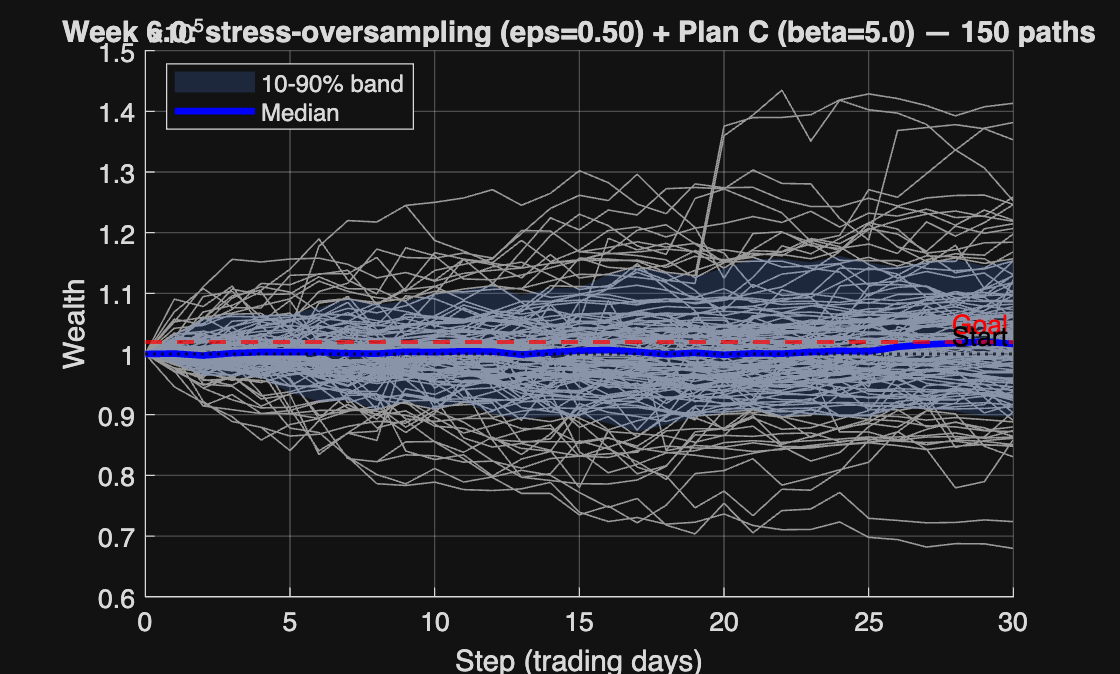

figure('Name','Hold-out wealth paths (Week 6.0 stress-oversampling + Plan C)');
hold on;

allPathsFlat = nan(nSeeds * numEvalEpisodes, horizonPeriods + 1);
rowCursor = 0;
for sIdx = 1:nSeeds
    paths = allWealthPathsBySeed{sIdx};
    for ep = 1:numel(paths)
        if ~isempty(paths{ep})
            rowCursor = rowCursor + 1;
            allPathsFlat(rowCursor, :) = paths{ep}';
        end
    end
end
allPathsFlat = allPathsFlat(1:rowCursor, :);

steps = 0:horizonPeriods;

for r = 1:size(allPathsFlat, 1)
    plot(steps, allPathsFlat(r, :), 'Color', [0.6 0.6 0.6 0.15], ...
        'LineWidth', 0.6, 'HandleVisibility', 'off');
end

p10 = prctile(allPathsFlat, 10, 1);
p90 = prctile(allPathsFlat, 90, 1);
fill([steps, fliplr(steps)], [p10, fliplr(p90)], [0.3 0.5 0.9], ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '10-90% band');
plot(steps, median(allPathsFlat, 1, 'omitnan'), 'b-', 'LineWidth', 2.5, ...
    'DisplayName', 'Median');

yline(goalWealth, '--r', 'Goal', 'LineWidth', 1.5, 'HandleVisibility', 'off');
yline(initialWealth, ':k', 'Start', 'LineWidth', 1.2, 'HandleVisibility', 'off');

xlabel('Step (trading days)');
ylabel('Wealth');
title(sprintf('Week 6.0: stress-oversampling (eps=%.2f) + Plan C (beta=%.1f) — %d paths', ...
    EPSILON_WEIGHT, BETA, rowCursor));
legend('Location','best');
grid on;

## Local Functions

function [R, M_z] = inputTestData(priceFile, macroFile, macroMean, macroStd)
    pricesTT = readtable(priceFile, 'VariableNamingRule', 'preserve');
    P = pricesTT{:, 2:end};
    R = diff(log(P));

    macroTT = readtable(macroFile, 'VariableNamingRule', 'preserve');
    M = macroTT{:, 2:end};
    M_z = (M - macroMean) ./ macroStd;
end